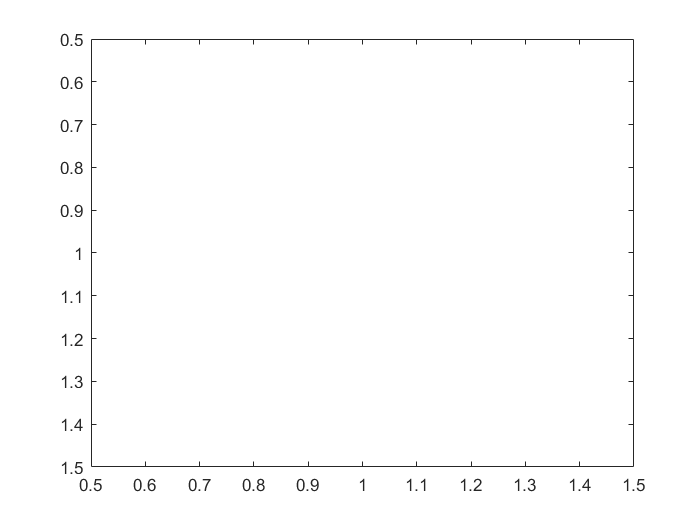

% Question 2:
StreamOut = EncodeImage_RLE(M8bit);
%

% Question 3:
[N,M] = size(M8bit);
Save8bitStream('Parede.str',N,M,StreamOut);

% Question 4:
Im = Load8bitStream('Parede.str');
Im = uint8(Im);
figure(103);
image(Im);
colormap(ColorMap);



%%
% Question 6:
[Ns,Ms,StreamIn] = Load8bitStream('Parede.str');


%%
% Question 7:
Ims = DecodeImage_RLE(Ns,Ms,StreamIn);
figure(107);
image(Ims);
colormap(ColorMap);

**Ex.1 **Carregue para o workspace do MATLAB o conteúdo da imagem guardada no ficheiro ‘Parede_8bit.bmp’ que se encontra no Moodle (nesta imagem, a cor de cada pixel é armazenada em 8 bits). Para tal, use o comado: ≫ [𝐼𝑚𝑎𝑔𝑒, 𝐶𝑜𝑙𝑜𝑟𝑀𝑎𝑝] = 𝑖𝑚𝑟𝑒𝑎𝑑(′𝑃𝑎𝑟𝑒𝑑𝑒_8𝑏𝑖𝑡. 𝑏𝑚𝑝 ′ ); ficando a informação na matriz (𝑁 × 𝑀) 𝐼𝑚𝑎𝑔𝑒. Visualize a imagem no MATLAB.

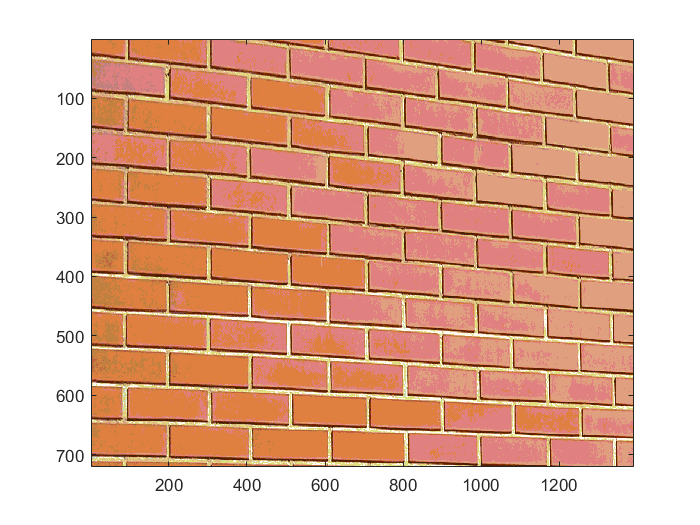

[Image,ColorMap] = imread('Parede_8bit.bmp');
colormap(ColorMap);

image(Image);

**Ex. 2 **Implemente uma função que proceda à **compressão** (sem perdas) da informação contida na matriz da imagem com base no algoritmo** RLE** (Run-Length Encoding): 𝑆𝑡𝑟𝑒𝑎𝑚 = 𝑬𝒏𝒄𝒐𝒅𝒆𝑰𝒎𝒂𝒈𝒆_𝑹𝑳𝑬(𝐼𝑚𝑎𝑔𝑒) O resultado desta função é uma sequência de bytes (do tipo uint8), guardados no vetor (𝐾 × 1) 𝑆𝑡𝑟𝑒𝑎𝑚, correspondente à compressão efetuada na matriz 𝐼𝑚𝑎𝑔𝑒, onde o varrimento deverá ser efetuado preferencialmente ao **longo dos pixéis de cada linha.** Note que, como o número de ocorrências consecutivas de cada cor é armazenado num uint8, esta função deverá atender a esta limitação

function Stream= Encode_Image_RLE(Image)
    [N,M] = size(Image);
    k = 1; %ponteiro para o array stream
    Stream(k,1) = Image(1,1);
    Count = uint8(0); 
    for n=1:N
        for m=1:M
            if Image(n,m) == Stream(k,1)
                
                if Count == 255 %Count só pode ir ate 2^8
                    k = k + 1; %
                    Stream(k,1) = Count;
                    k = k + 1; 
                    Stream(k,1) = Image(n,m);
                    Count = 0;
                end
                Count = Count + 1;
            else %prox simbolo
                k = k + 1;
                Stream(k,1) = Count;
                k = k + 1;
                Stream(k,1) = Image(n,m);
                Count = 1;
            end
        end
    end
    k = k + 1;
    Stream(k,1) = Count;
end

**Ex. 3 **

Pretendo **guardar num ficheiro de menor tamanho** que o original a informação resultante da aplicação do método RLE, desenvolva a função: 𝑺𝒂𝒗𝒆𝟖𝒃𝒊𝒕𝑺𝒕𝒓𝒆𝒂𝒎(𝐹𝑖𝑙𝑒𝑛𝑎𝑚𝑒, 𝑁, 𝑀, 𝑆𝑡𝑟𝑒𝑎𝑚) que guarda no ficheiro indicado por 𝐹𝑖𝑙𝑒𝑛𝑎𝑚𝑒 a sequência de dados produzida pela função da pergunta anterior. Esse ficheiro começa por conter os valores de 𝑁 e 𝑀 (no formato uint16), seguindo-se o conteúdo de 𝑆𝑡𝑟𝑒𝑎𝑚 (no formato uint8). Teste com a imagem em análise e verifique a taxa de compressão que foi possível obter.

function Save8bitStream(Filename, N, M, Stream)
    fid = fopen(Filename,'wb');
    fwrite(fid,N,'uint16');
    fwrite(fid,M,'uint16');
    fwrite(fid,Stream,'uint8');
    fclose(fid);
end

%  Saves a NxM compressed 8 bit image that is given through the 8 bit data
%  stream Stream (a Kx1 vector).
%  The file is named Filename, and it starts by saving N (uint16) and M
%  (uint16), followed by the 8 bit stream.


**Ex. 4 **O mesmo mas agora a função lê

function  [N,M,Stream]=  Load8bitStream(Filename)
    fid = fopen(Filename,'rb');
    N= fread(fid,1,'uint16');
    M= fread(fid,1,'uint16');
    Stream= fread(fid);
end


**Ex. 5 Descodificar ** a mensagem comprimida

volta a **gerar a matriz dos pixéis** da imagem que é obtida por interpretação da informação contida em 𝑆𝑡𝑟𝑒𝑎𝑚 (sequência de dados produzida pelo RLE). Teste a função visualizando a imagem resultante (que terá que ser igual à imagem original).

function Image= DecodeImage_RLE(N,M,Stream)
    Image= uint8(zeros(N,M)); %imagem do zero
    n=1;
    m=1;
    for k=1:2:length(Stream) %percorrer os simbolos
        Code=Stream(k); %um simbolo
        Num=Stream(k+1); % as vezes q ele aparece
        for j=1:Num %para ver quantas vezes ele aparece
            Image(n,m)=Code; %poe aquele simbolo j vezes
            m=m+1; 
            if m>M %quando atinge o maximo, muda de linha
                m=1;
                n=n+1;
                
            end
        end
    end
end

%  Decodes a stream of 8 bit data that resulted from compressing an image
%  (8 bit resolution) with the RLE (Run-Length Encoding) algorithm,
%  implemented through the function EncodeImage_RLE.
    
    